**Question 1**

close all; %close all figure windows
clear all; % clear all variables in workspace
clc; % clear command prompt window
% clf = means clear the current figure window but
% keep it open. 


% Plotting sin(x), cos(x)
x = -4*pi : pi/20 : 4*pi;
% or linspace(-4pi, 4pi, 10000) - 10000 equally
% spaced points on -4pi to 4pi

figure(1)

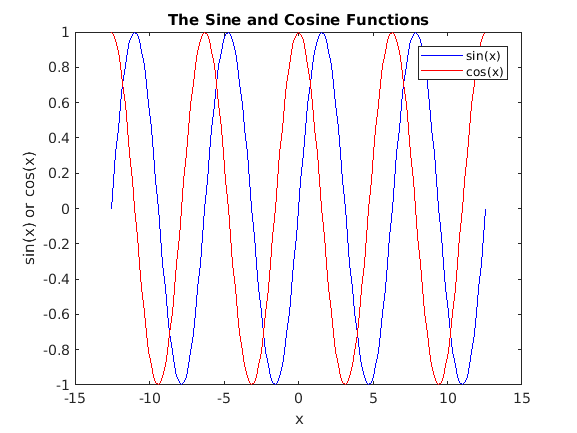

plot(x, sin(x), 'b-', x, cos(x), 'r-')
xlabel('x')
ylabel('sin(x) or cos(x)')
title('The Sine and Cosine Functions')
legend('sin(x)', 'cos(x)')


%hold on
%plot([-5 -5], [-1 1])

**Question 2**

close all; % figure windows
clear all; % vars in workspace
clc; % clear command prompt

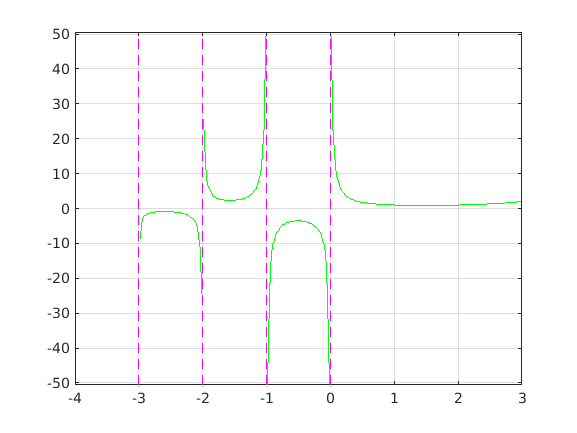


% evaluating gamma, but avoiding the asymptotes
% that are at x = -3, -2, -1, 0
% plot magenta dashed lines at asymptotes

xs = -3: 0.02 :3;
ys = gamma(xs);

plotGammaWithAsymptotes(xs, ys)

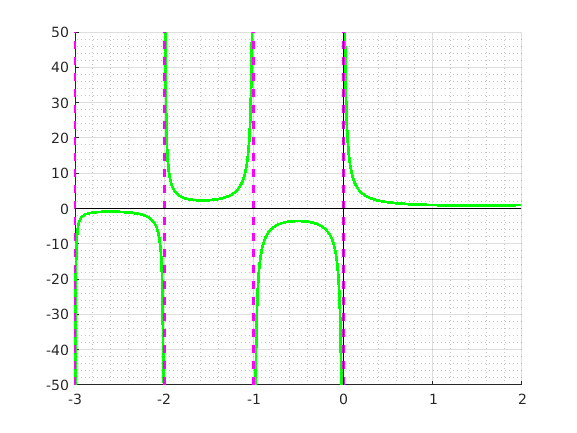

plotGraphAsymptotes(@(x) gamma(x), -3, 2, 50)

**Question 3**

Plotting y = 2x^2 + 8x-1 on [-5,5] and draw y = 0, x = 0 and plot the intercepts of the graph along with the vertex as circles. Then label the x and y axes and place a legend on the graph. 

close all; clear all; clc; clf

a = 2; b = 8; c = -1; 
p = [a, b, c];

xs = -5 : 0.01 : 5; 
y = @(x) a*x .^ 2 + b*x + c;
ys = y(xs);

% Range
xMin = min(xs); xMax = max(xs); 
yMin = min(ys); yMax = max(ys);

% Vertex
vx = -b/(2*a);
vy = c - b^2/(4*a);

% Intercepts
xIntercepts = roots(p) % solutions in Prac

xIntercepts =   -4.121320343559643
   0.121320343559643


% find this by hand
yIntercept = y(0)

yIntercept =     -1


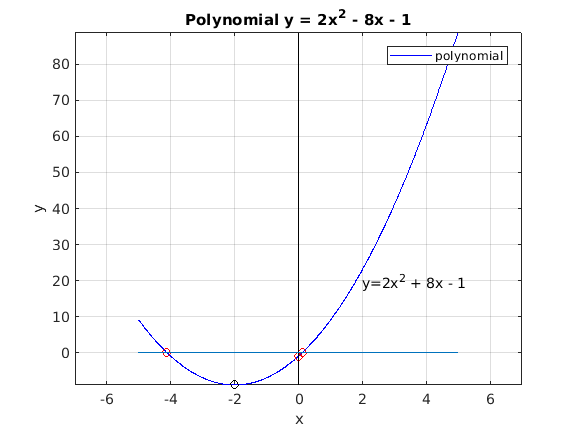

% Plotting main graph
plot(xs, ys, 'b-')
axis([xMin-2, xMax+2, yMin, yMax])
grid on
hold on 

% Plotting the vertex
plot(vx, vy, 'ko')

% And plotting x,y intercepts (at most only 2
% x intercepts occur)
plot(xIntercepts(1), 0, 'ro')
plot(xIntercepts(2), 0, 'ro')
plot(0, yIntercept, 'ro')

% Plotting the x and y-axes
plot([0 0], [yMin yMax], 'k-') % y-axis
plot([xMin xMax], [0 0]) % x-axis

xlabel('x')
ylabel('y')
title('Polynomial y = 2x^2 - 8x - 1')
legend('polynomial')
% left-hand tip at point (2,20)
text(2, 20, 'y=2x^2 + 8x - 1') % at point (2,20)


% TODO - fix getintercepts file, got away
% this time using roots in matlab optimization
% package!

**Question 4: **

volumeTetrahedron(2)

ans =    0.942809041582063


showVolume

The volume of a tetrahedron with equilaterial triangle side lengths of 5.00000 is: 14.73139


**Question 5: Fluids viscosity graphs**

clear; 

% get force value, getting other data. 
force = input('Enter a value for impulse force: ');
while ~isnumeric(force) || ~isscalar(force)
    disp('You must enter a numeric scalar value.');
    force = input('Enter the force magnitude: ');
end

%fluidsData = [0.246 0.806; 0.25 1; 0.643 1.213];
numFluids = input('How many fluids?: ');
fluidsData = zeros(numFluids, 2);
fluidNames = strings(1, numFluids);

% Now input fluids data
for i = 1:numFluids
    % HELP THIS DOESN"T DETECT things like '3r'
    name = input('What is the fluid name?: ', 's');
    while ~ischar(name)
        name = input('Invalid, must enter a name: ', 's');
    end
    fluidNames(i) = name; 
    fluidsData(i, 1) = input('a = ');
    fluidsData(i, 2) = input('b = ');
end

% Making different ys for different fluids
xs = linspace(0, 20, 1000); %0 : 0.01 : 20;
ysEthyl = makeFluidYs(xs, force, fluidsData(1,:));
ysWater = makeFluidYs(xs, force, fluidsData(2,:));
ysOil = makeFluidYs(xs, force, fluidsData(3,:));
allYs = [ysEthyl; ysWater; ysOil];

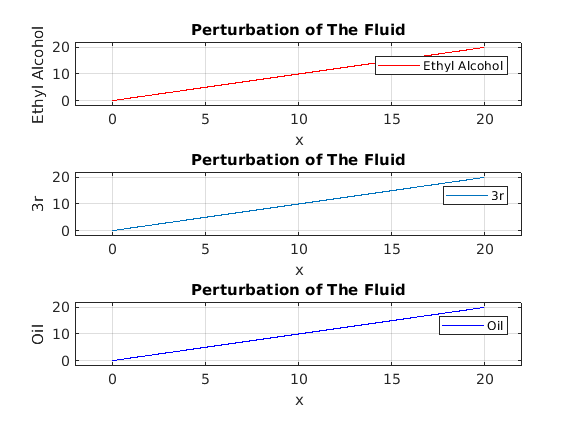

% Creating plot 
clf
colors = ['r-', 'b-', 'g-'];
%fluidNames = ['ethyl alcohol', 'water', 'oil']
for i = 1:numFluids
    subplot(3, 1, i) % 3 rows 1 col, this one (i)
    plot(xs, allYs(i, :), colors(i))
    axis([min(xs)-2, max(xs)+2, min(allYs(i,:))-2, max(allYs(i,:))+2])
    
    grid on
    xlabel('x')
    ylabel(fluidNames(i))
    title('Perturbation of The Fluid')
    legend(fluidNames(i))
end

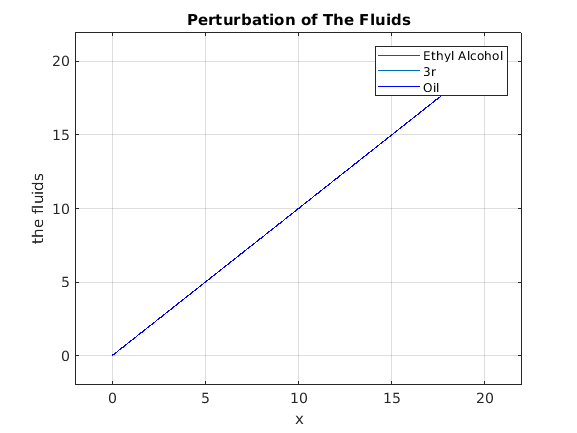


% And another plot for all three together
subplot(1,1,1) %reset

for i = 1:numFluids
    plot(xs, allYs(i, :), colors(i))
    axis([min(xs)-2, max(xs)+2, min(allYs(i,:))-2, max(allYs(i,:))+2])
    grid on
    hold on
end

legend(fluidNames)
xlabel('x')
ylabel('the fluids')
title('Perturbation of The Fluids')

**Question 6: **

for i = -2:14
    fprintf('i = %d, measure = %s\n', i, beaufortMeasure(i))
end

i = -2, measure = INVALID
i = -1, measure = INVALID
i = 0, measure = There is no wind
i = 1, measure = There is a breeze
i = 2, measure = There is a breeze
i = 3, measure = There is a breeze
i = 4, measure = There is a breeze
i = 5, measure = There is a breeze
i = 6, measure = There is a breeze
i = 7, measure = There is a gale
i = 8, measure = There is a gale
i = 9, measure = There is a gale
i = 10, measure = It is a storm
i = 11, measure = It is a storm
i = 12, measure = Hello, Hurricane
i = 13, measure = INVALID
i = 14, measure = INVALID
